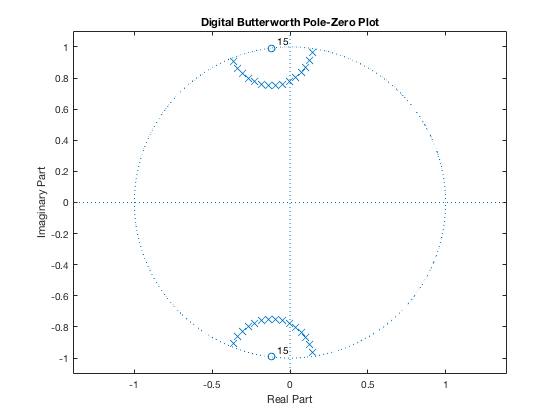

%passband frequencies

fp1 = 9e6;
fp2 = 12.5e6;

%stopband frequencies

fs1 = 9.5e6;
fs2 = 12e6;

rp = 1.5;  %passband deviation
rs = 40;   %stop band deviation

fs = 40e6;  %sampling frequency

%digital normalized frequencies

Fp = [fp1, fp2] / (fs/2);
Fs = [fs1, fs2] / (fs/2);

%x-axis for plotting

f = linspace(0, 20e6, 1000); %for digital
w = 2*pi*f; %for analog

fMHz = f/1e6;

%radian frequencies for analog filters
Wp = 2*pi*Fp*(fs/2);
Ws = 2*pi*Fs*(fs/2);


%Case I: Digital Butterworth Filter

[n_butter, Wn_butter] = buttord(Fp, Fs, rp, rs);

[z_butter, p_butter, ~] = butter(n_butter, Wn_butter, 'stop');

[H_butter, ~] = freqz(poly(z_butter), poly(p_butter), f, fs);

mag_dB_butter = 20 * log10(abs(H_butter));

phaseAng_butter = unwrap(angle(H_butter)) * 180 / pi;



figure;
zplane(z_butter, p_butter);
title('Digital Butterworth Pole-Zero Plot');

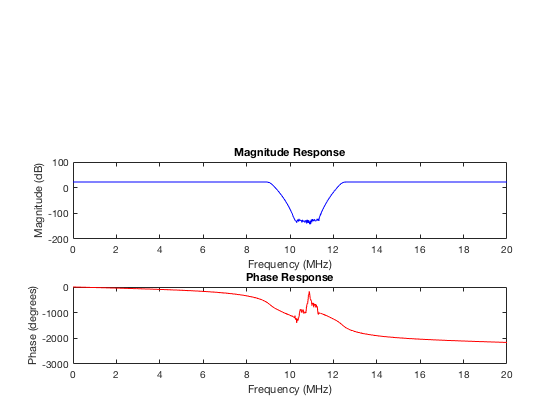


figure('name', 'Digital Butterworth Filter');

subplot(3, 1, 2);
plot(fMHz, mag_dB_butter, 'b');
title('Magnitude Response');
xlabel('Frequency (MHz)');
ylabel('Magnitude (dB)');

subplot(3, 1, 3);
plot(fMHz, phaseAng_butter, 'r');
title('Phase Response');
xlabel('Frequency (MHz)');
ylabel('Phase (degrees)');


disp('Digital Butterworth Filter:');

Digital Butterworth Filter:


disp('Filter Order:');

Filter Order:


disp(n_butter*2);

    30



disp('Peak Passband gain:');

Peak Passband gain:


disp(max(mag_dB_butter));

   22.2881




disp('Gain at 9MHz:');

Gain at 9MHz:


disp(mag_dB_butter(450));

   21.1551




disp('Gain at 9.5MHz:');

Gain at 9.5MHz:


disp(mag_dB_butter(475));

  -16.6184




disp('Gain at 12MHz:');

Gain at 12MHz:


disp(mag_dB_butter(600));

  -18.5916




disp('Gain at 12.5MHz:');

Gain at 12.5MHz:


disp(mag_dB_butter(625));

   21.3192



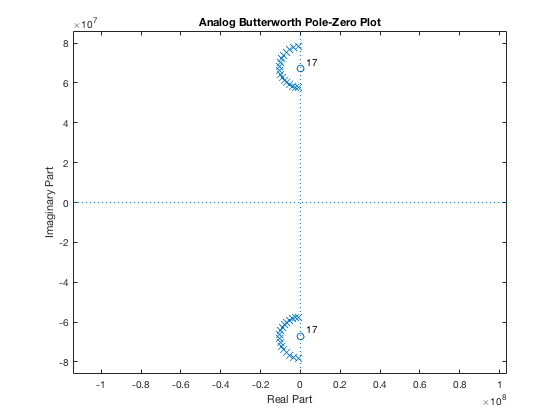



%Case II: Analog Butterworth Filter

[n_butter_analog, Wn_butter_analog] = buttord(Wp, Ws, rp, rs, 's');

[z_butter_analog, p_butter_analog, ~] = butter(n_butter_analog, Wn_butter_analog, 'stop', 's');

[H_butter_analog, ~]= freqs(poly(z_butter_analog), poly(p_butter_analog), w);

mag_dB_butter_analog = 20 * log10(abs(H_butter_analog));

phaseAng_butter_analog = unwrap(angle(H_butter_analog)) * 180 / pi;

figure;
zplane(z_butter_analog, p_butter_analog);
title('Analog Butterworth Pole-Zero Plot');

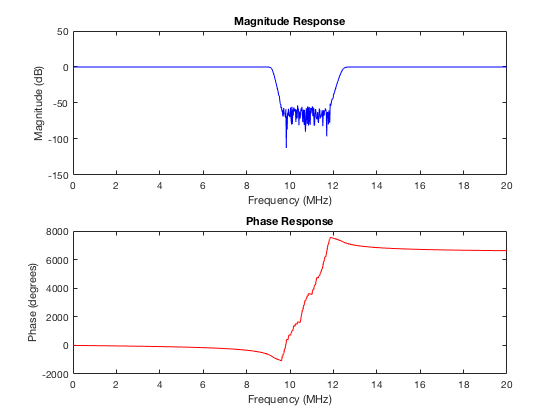


figure('name', 'Analog Butterworth Filter');

subplot(2, 1, 1);
plot(fMHz, mag_dB_butter_analog, 'b');
title('Magnitude Response');
xlabel('Frequency (MHz)');
ylabel('Magnitude (dB)');

subplot(2, 1, 2);
plot(fMHz, phaseAng_butter_analog, 'r');
title('Phase Response');
xlabel('Frequency (MHz)');
ylabel('Phase (degrees)');


disp('Analog Butterworth Filter:');

Analog Butterworth Filter:


disp('Filter Order:');

Filter Order:


disp(n_butter_analog*2);

    34




disp('Peak Passband gain:');

Peak Passband gain:


disp(max(mag_dB_butter_analog));

   5.2027e-04




disp('Gain at 9MHz:');

Gain at 9MHz:


disp(mag_dB_butter_analog(450));

   -0.0772




disp('Gain at 9.5MHz:');

Gain at 9.5MHz:


disp(mag_dB_butter_analog(475));

  -39.5189




disp('Gain at 12MHz:');

Gain at 12MHz:


disp(mag_dB_butter_analog(600));

  -42.1999




disp('Gain at 12.5Mhz:');

Gain at 12.5Mhz:


disp(mag_dB_butter_analog(625));

   -1.4909



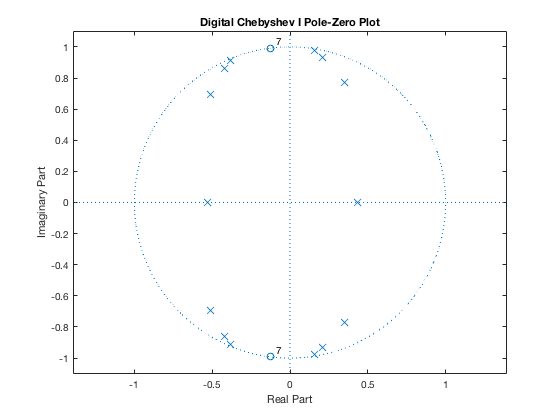



%Case III: Digital Chebyshev I

[n_cheb1, Wn_cheb1] = cheb1ord(Fp, Fs, rp, rs);

[z_cheb1, p_cheb1, ~] = cheby1(n_cheb1, rp, Wn_cheb1, 'stop');


[H_cheb1, ~]= freqz(poly(z_cheb1), poly(p_cheb1), f, fs);

mag_dB_cheb1 = 20 * log10(abs(H_cheb1));

phaseAng_cheb1 = unwrap(angle(H_cheb1)) * 180 / pi;

figure;
zplane(z_cheb1, p_cheb1);
title('Digital Chebyshev I Pole-Zero Plot');

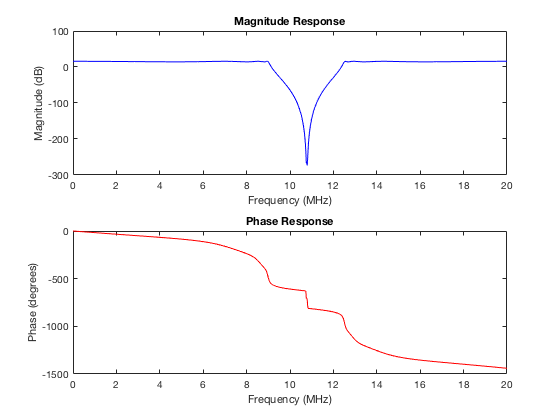


figure('name', 'Digital Chebyshev I Filter');

subplot(2, 1, 1);
plot(fMHz, mag_dB_cheb1, 'b');
title('Magnitude Response');
xlabel('Frequency (MHz)');
ylabel('Magnitude (dB)');

subplot(2, 1, 2);
plot(fMHz, phaseAng_cheb1, 'r');
title('Phase Response');
xlabel('Frequency (MHz)');
ylabel('Phase (degrees)');


disp('Digital Chebyshev I:');

Digital Chebyshev I:


disp('Filter Order:');

Filter Order:


disp(n_cheb1*2);

    14




disp('Peak Passband gain:');

Peak Passband gain:


disp(max(mag_dB_cheb1));

   15.8550




disp('Gain at 9Mhz:');

Gain at 9Mhz:


disp(mag_dB_cheb1(450));

   15.0480




disp('Gain at 9.5Mhz:');

Gain at 9.5Mhz:


disp(mag_dB_cheb1(475));

  -26.3781




disp('Gain at 12Mhz:');

Gain at 12Mhz:


disp(mag_dB_cheb1(600));

  -29.7008




disp('Gain at 12.5Mhz:');

Gain at 12.5Mhz:


disp(mag_dB_cheb1(625));

   13.7256



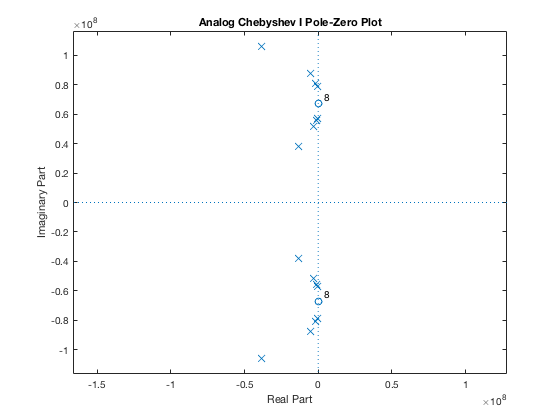



% Case IV: Analog Chebyshev I

[n_cheb1_analog, Wn_cheb1_analog] = cheb1ord(Wp, Ws, rp, rs, 's');

[z_cheb1_analog, p_cheb1_analog, ~] = cheby1(n_cheb1_analog, rp, Wn_cheb1_analog, 'stop', 's');

[H_cheb1_analog, ~]= freqs(poly(z_cheb1_analog), poly(p_cheb1_analog), w);

mag_dB_cheb1_analog = 20 * log10(abs(H_cheb1_analog));

phaseAng_cheb1_analog = unwrap(angle(H_cheb1_analog)) * 180 / pi;

figure;
zplane(z_cheb1_analog, p_cheb1_analog);
title('Analog Chebyshev I Pole-Zero Plot');

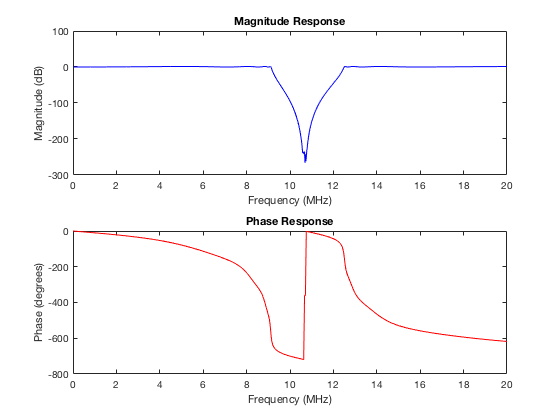


figure('name', 'Analog Chebyshev I Filter');

subplot(2, 1, 1);
plot(fMHz, mag_dB_cheb1_analog, 'b');
title('Magnitude Response');
xlabel('Frequency (MHz)');
ylabel('Magnitude (dB)');

subplot(2, 1, 2);
plot(fMHz, phaseAng_cheb1_analog, 'r');
title('Phase Response');
xlabel('Frequency (MHz)');
ylabel('Phase (degrees)');


disp('Analog Chebyshev I:');

Analog Chebyshev I:


disp('Filter Order:');

Filter Order:


disp(n_cheb1_analog*2);

    16




disp('Peak Passband gain:');

Peak Passband gain:


disp(max(mag_dB_cheb1_analog));

    1.5000




disp('Gain at 9Mhz:');

Gain at 9Mhz:


disp(mag_dB_cheb1_analog(450));

    0.0394




disp('Gain at 9.5Mhz:');

Gain at 9.5Mhz:


disp(mag_dB_cheb1_analog(475));

  -44.3656




disp('Gain at 12Mhz:');

Gain at 12Mhz:


disp(mag_dB_cheb1_analog(600));

  -45.9420




disp('Gain at 12.5Mhz:');

Gain at 12.5Mhz:


disp(mag_dB_cheb1_analog(625));

   -0.6797



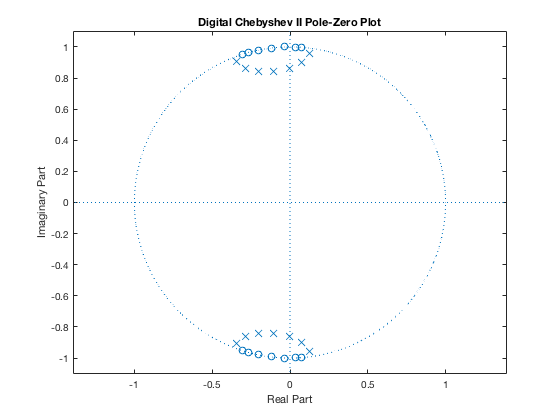



%Case V: Digital Chebyshev II
%fix

[n_cheb2, Wn_cheb2] = cheb2ord(Fp, Fs, rp, rs);

[z_cheb2, p_cheb2, ~] = cheby2(n_cheb2, rs, Wn_cheb2, 'stop');


[H_cheb2, ~]= freqz(poly(z_cheb2), poly(p_cheb2), f, fs);

mag_dB_cheb2 = 20 * log10(abs(H_cheb2));

phaseAng_cheb2 = unwrap(angle(H_cheb2)) * 180 / pi;

figure;
zplane(z_cheb2, p_cheb2);
title('Digital Chebyshev II Pole-Zero Plot');

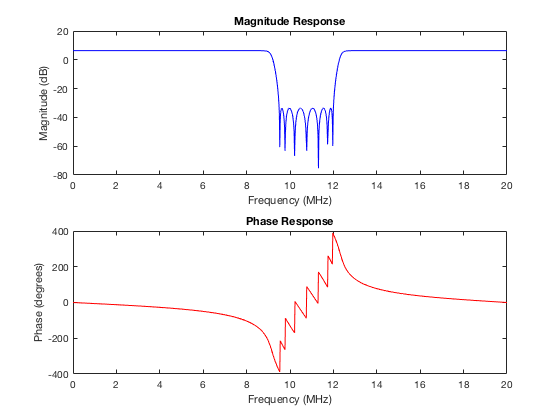


figure('name', 'Digital Cheybshev II Filter');

subplot(2, 1, 1);
plot(fMHz, mag_dB_cheb2, 'b');
title('Magnitude Response');
xlabel('Frequency (MHz)');
ylabel('Magnitude (dB)');


subplot(2, 1, 2);
plot(fMHz, phaseAng_cheb2, 'r');
title('Phase Response');
xlabel('Frequency (MHz)');
ylabel('Phase (degrees)');


disp('Digital Chebyshev II Filter:');

Digital Chebyshev II Filter:


disp('Filter Order:');

Filter Order:


disp(n_cheb2*2);

    14



disp('Peak Passband gain:');

Peak Passband gain:


disp(max(mag_dB_cheb2));

    6.3499




disp('Gain at 9MHz:');

Gain at 9MHz:


disp(mag_dB_cheb2(450));

    5.6593




disp('Gain at 9.5MHz:');

Gain at 9.5MHz:


disp(mag_dB_cheb2(475));

  -30.4728




disp('Gain at 12MHz:');

Gain at 12MHz:


disp(mag_dB_cheb2(600));

  -36.9030




disp('Gain at 12.5MHz:');

Gain at 12.5MHz:


disp(mag_dB_cheb2(625));

    5.7297



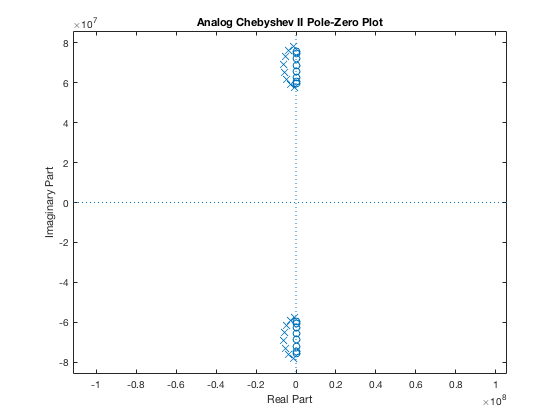



%Case VI: Analog Chebyshev II

[n_cheb2_analog, Wn_cheb2_analog] = cheb2ord(Wp, Ws, rp, rs, 's');

[z_cheb2_analog, p_cheb2_analog, ~] = cheby2(n_cheb2_analog, rs, Wn_cheb2_analog, 'stop', 's');


[H_cheb2_analog, ~]= freqs(poly(z_cheb2_analog), poly(p_cheb2_analog), w);

mag_dB_cheb2_analog = 20 * log10(abs(H_cheb2_analog));

phaseAng_cheb2_analog = unwrap(angle(H_cheb2_analog)) * 180 / pi;

figure;
zplane(z_cheb2_analog, p_cheb2_analog);
title('Analog Chebyshev II Pole-Zero Plot');

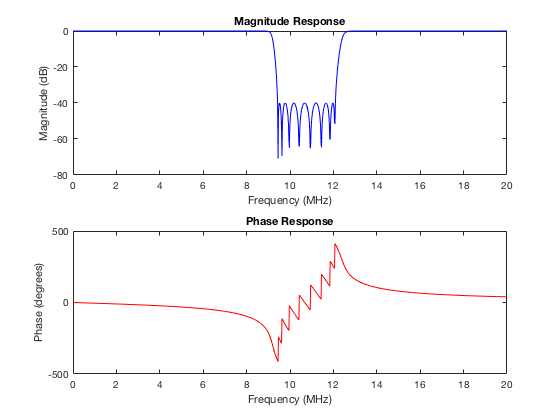


figure('name', 'Analog Cheybshev II Filter');

subplot(2, 1, 1);
plot(fMHz, mag_dB_cheb2_analog, 'b');
title('Magnitude Response');
xlabel('Frequency (MHz)');
ylabel('Magnitude (dB)');
%ylim([-50, 2]); % Set the vertical axis range

subplot(2, 1, 2);
plot(fMHz, phaseAng_cheb2_analog, 'r');
title('Phase Response');
xlabel('Frequency (MHz)');
ylabel('Phase (degrees)');


disp('Analog Chebyshev II Filter:');

Analog Chebyshev II Filter:


disp('Filter Order:');

Filter Order:


disp(n_cheb2_analog*2);

    16



disp('Peak Passband gain:');

Peak Passband gain:


disp(max(mag_dB_cheb2_analog));

  -1.0415e-13




disp('Gain at 9Mhz:');

Gain at 9Mhz:


disp(mag_dB_cheb2_analog(450));

   -0.2010




disp('Gain at 9.5MHz:');

Gain at 9.5MHz:


disp(mag_dB_cheb2_analog(450));

   -0.2010




disp('Gain at 12MHz:');

Gain at 12MHz:


disp(mag_dB_cheb2_analog(600));

  -40.1697




disp('Gain at 12.5MHz:');

Gain at 12.5MHz:


disp(mag_dB_cheb2_analog(625));

   -1.6319



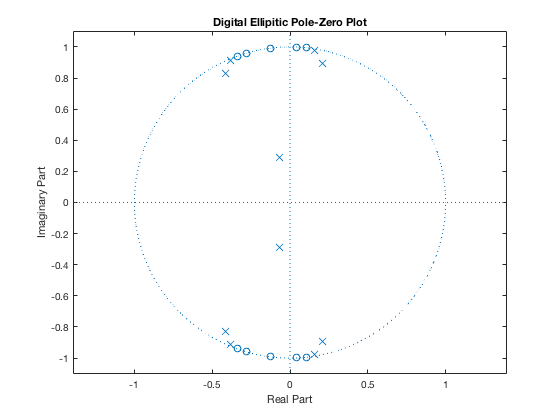



%Case VII: Digital Elliptic Filter

[n_ellip, Wn_ellip] = ellipord(Fp, Fs, rp, rs);

[z_ellip, p_ellip, ~] = ellip(n_ellip, rp, rs, Fp, 'stop');


[H_ellip, ~]= freqz(poly(z_ellip), poly(p_ellip), f, fs);

mag_dB_ellip = 20 * log10(abs(H_ellip));

phaseAng_ellip = unwrap(angle(H_ellip)) * 180 / pi;

figure;
zplane(z_ellip, p_ellip);
title('Digital Ellipitic Pole-Zero Plot');

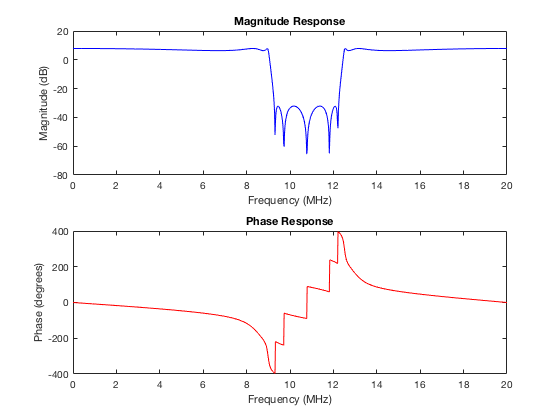


figure('name', 'Digital Elliptic Filter');

subplot(2, 1, 1);
plot(fMHz, mag_dB_ellip, 'b');
title('Magnitude Response');
xlabel('Frequency (MHz)');
ylabel('Magnitude (dB)');
%ylim([-50, 2]); % Set the vertical axis range

subplot(2, 1, 2);
plot(fMHz, phaseAng_ellip, 'r');
title('Phase Response');
xlabel('Frequency (MHz)');
ylabel('Phase (degrees)');


disp('Digital Elliptic Filter:');

Digital Elliptic Filter:


disp('Filter Order:');

Filter Order:


disp(n_ellip*2);

    10



disp('Peak Passband gain:');

Peak Passband gain:


disp(max(mag_dB_ellip));

    7.8663




disp('Gain at 9MHz:');

Gain at 9MHz:


disp(mag_dB_ellip(450));

    7.0468




disp('Gain at 9.5MHz:');

Gain at 9.5MHz:


disp(mag_dB_ellip(475));

  -32.5747




disp('Gain at 12MHz:');

Gain at 12MHz:


disp(mag_dB_ellip(600));

  -34.0076




disp('Gain at 12.5Mhz:');

Gain at 12.5Mhz:


disp(mag_dB_ellip(625));

    5.7394



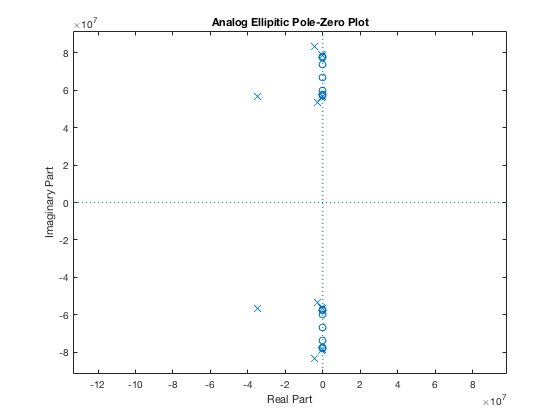



%Case VIII: Analog Elliptic Filter

[n_ellip_analog, Wn_ellip_analog] = ellipord(Wp, Ws, rp, rs, 's');

[z_ellip_analog, p_ellip_analog, ~] = ellip(n_ellip_analog, rp, rs, Wp, 'stop', 's');


[H_ellip_analog, ~]= freqs(poly(z_ellip_analog), poly(p_ellip_analog), w);

mag_dB_ellip_analog = 20 * log10(abs(H_ellip_analog));

phaseAng_ellip_analog = unwrap(angle(H_ellip_analog)) * 180 / pi;

figure;
zplane(z_ellip_analog, p_ellip_analog);
title('Analog Ellipitic Pole-Zero Plot');

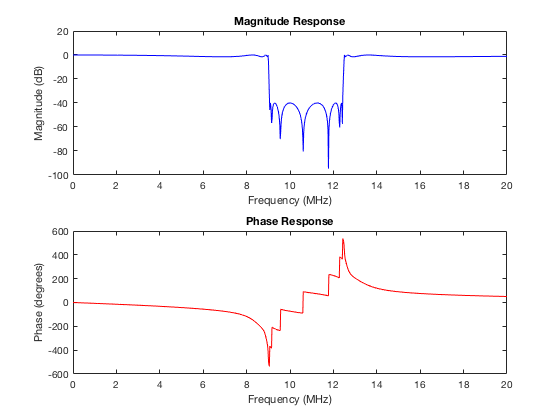


figure('name', 'Analog Elliptic Filter');

subplot(2, 1, 1);
plot(fMHz, mag_dB_ellip_analog, 'b');
title('Magnitude Response');
xlabel('Frequency (MHz)');
ylabel('Magnitude (dB)');
%ylim([-50, 2]); % Set the vertical axis range

subplot(2, 1, 2);
plot(fMHz, phaseAng_ellip_analog, 'r');
title('Phase Response');
xlabel('Frequency (MHz)');
ylabel('Phase (degrees)');


disp('Analog Elliptic Filter:');

Analog Elliptic Filter:


disp('Filter Order:');

Filter Order:


disp(n_ellip_analog*2);

    14



disp('Peak Passband gain:');

Peak Passband gain:



disp(max(mag_dB_ellip_analog));

   8.4861e-14




disp('Gain at 9MHz:');

Gain at 9MHz:


disp(mag_dB_ellip_analog(450));

   -0.0764




disp('Gain at 9.5MHz:');

Gain at 9.5MHz:


disp(mag_dB_ellip_analog(475));

  -49.9826




disp('Gain at 12MHz:');

Gain at 12MHz:


disp(mag_dB_ellip_analog(600));

  -41.8502




disp('Gain at 12.5Mhz:');

Gain at 12.5Mhz:


disp(mag_dB_ellip_analog(625));

   -4.2106

